## Using "stepsinfo()" function

The "stepinfo()" function need only step response. The signal generator block generate the periodic function. So, you would like to cut the one step response.

clc; clear;

y = simout.y;
t = simout.tout;

plot(y)
xlabel('index');

Using 'plot(y)' to find the index of step response.

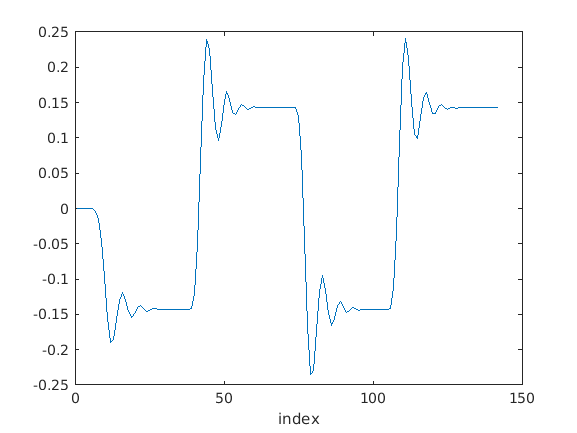

ans = struct with fields:
        RiseTime: 0.9180
    SettlingTime: 33.2033
     SettlingMin: 0.0959
     SettlingMax: 0.2387
       Overshoot: 67.1706
      Undershoot: 99.5784
            Peak: 0.2387
        PeakTime: 27.1195


indexfi = 39; indexst = 72;
stepinfo(y(indexfi:indexst),t(indexfi:indexst))